tracks_matrix = h5read('track.analysis.h5','/tracks');
% frames x nodes x 2 x tracks

% identify 2 main tracks
nose_tracks = squeeze(tracks_matrix(:,1,1,:));
sum_nan = sum(isnan(nose_tracks),1);
% find smallest 2
[~,c] = sort(sum_nan);
main_track_id = c(1:2);
main_tracks = tracks_matrix(:,:,:,main_track_id);
other_tracks = tracks_matrix(:,:,:,setdiff(1:size(tracks_matrix,4), main_track_id));

new_track = [];
frame_need_attention = [];
for i = 1:size(main_tracks,1);
    temp_main = main_tracks(i,:,:,:);
    temp_main = reshape(temp_main, 1, []);
    mouse1_main = temp_main(1:4);
    mouse2_main = temp_main(5:8);
    temp_other = reshape(other_tracks(i,:,:,:),1,[]);
    nanID1 = find(isnan(mouse1_main));
    nanID2 = find(isnan(mouse2_main));
    if ~isempty(nanID1) % if there are nans in main track
         % first try get the info from other tracks
        other_track = reshape(other_tracks(i,:,:,:),[],4);
        other_track = other_track(and(~isnan(other_track(:,1)), ~isnan(other_track(:,3))),:);
        if ~isempty(other_track) % find the closest track from other tracks
           cor_diff = other_track - new_track(end,1:4);
           cor_diff = [cor_diff(:,1).^2 + cor_diff(:,2).^2, cor_diff(:,3).^2 + cor_diff(:,4).^2];
           cor_diff = mean(cor_diff, 2);
           [~, other_id] = sort(cor_diff);
           other_id = other_id(1);
           if sqrt(cor_diff) < 100 % an arbituary thereshold
                mouse1_main = other_track(other_id,:);
           end
        else
           mouse1_main = new_track(end,1:4);
        end
    end
    
    if ~isempty(nanID2) % if there are nans in main track
         % first try get the info from other tracks
        other_track = reshape(other_tracks(i,:,:,:),[],4);
        other_track = other_track(and(~isnan(other_track(:,1)), ~isnan(other_track(:,3))),:);
        if ~isempty(other_track) % find the closest track from other tracks
           cor_diff = other_track - new_track(end,1:4);
           cor_diff = [cor_diff(:,1).^2 + cor_diff(:,2).^2, cor_diff(:,3).^2 + cor_diff(:,4).^2];
           cor_diff = mean(cor_diff, 2);
           [~, other_id] = sort(cor_diff);
           other_id = other_id(1);
           if cor_diff < 100 % an arbituary thereshold
                mouse2_main = other_track(other_id,:);
           end
        else
           mouse2_main = new_track(end,5:8);
        end
    end
    new_track = [new_track; mouse1_main, mouse2_main];
%     temp(isnan(temp)) = [];
%     if length(temp) >= 8
%         new_track = [new_track;temp(1:8)];
%     else
%         temp = [temp,repmat(NaN,1,8-length(temp))];
%         new_track = [new_track;temp];
%         frame_need_attention = [frame_need_attention;i];
%     end
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

## center

track_center = [1/2*(new_track(:,1)+new_track(:,2)),1/2*(new_track(:,3)+new_track(:,4)),1/2*(new_track(:,5)+new_track(:,6)),1/2*(new_track(:,7)+new_track(:,8))];

## remove nans

## Quadrants

qcenter = [225,239]; % [xcenter, ycenter]
qcode = [track_center(:,1)<=qcenter(1), track_center(:,2) > qcenter(2), track_center(:,3)<=qcenter(1),track_center(:,4)>qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2,qcode(:,3)+qcode(:,4)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;

## visualize

vid = VideoReader('behav_video_crop.avi');
Arena = zeros(vid.Height,vid.Width,'uint8');
f = figure;
a = axes('Parent',f,'NextPlot','add');
are = imshow(Arena,'Parent',a);
a1 = line(a,new_track(1,[1,2]),new_track(1,[3,4]),'Color','white');
a2 = line(a,new_track(1,[5,6]),new_track(1,[7,8]),'Color','white');
c = plot(a, track_center(1,[1,3]),track_center(1,[2,4]),'Marker','*');
M1q = plot(224,178,'Marker','o');
M2q = plot(224,178,'Marker','o');
% viw = VideoWriter('track.avi','MPEG-4');
% viw.FrameRate = 30;
% open(viw);
% kw = waitbar(0)
for i = 1:size(new_track,1);
    cur_ = new_track(i,:);
    set(a1,'XData', cur_([1,2]), 'YData', cur_([3,4]));
    set(a2,'XData',cur_([5,6]),'YData',cur_([7,8]));
    set(c,'XData',track_center(i,[1,3]),'YData',track_center(i,[2,4]));
    set(are, 'CData', readFrame(vid));
    switch qseries(i,1)
        case 1
            set(M1q,'XData',qcenter(1)+20,'YData',qcenter(2)-20);
        case 2
            set(M1q,'XData',qcenter(1)+20,'YData',qcenter(2)+20);
        case 3
            set(M1q,'XData',qcenter(1)-20,'YData',qcenter(2)+20);
        case 4
            set(M1q,'XData',qcenter(1)-20,'YData',qcenter(2)-20);
    end
    switch qseries(i,2)
        case 1
            set(M2q,'XData',qcenter(1)+30,'YData',qcenter(2)-30);
        case 2
            set(M2q,'XData',qcenter(1)+30,'YData',qcenter(2)+30);
        case 3
            set(M2q,'XData',qcenter(1)-30,'YData',qcenter(2)+30);
        case 4
            set(M2q,'XData',qcenter(1)-30,'YData',qcenter(2)-30);
    end
%     s = getframe(a);
%     writeVideo(viw, s.cdata);
%     waitbar(i/6000,kw);
    drawnow;
%     pause(0.01);
end
% close(viw);
% delete(viw);


## Because didnot track individual animal, can only calculate total time spent

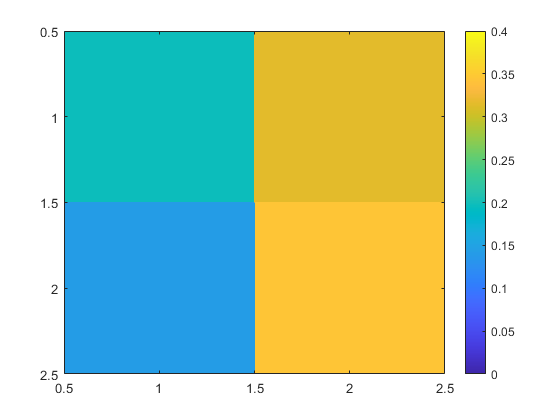

m_quadrant_perc = zeros(2,2);
m_quadrant_perc(1,2) = sum(qseries(:)==1);
m_quadrant_perc(2,2) = sum(qseries(:)==2);
m_quadrant_perc(2,1) = sum(qseries(:)==3);
m_quadrant_perc(1,1) = sum(qseries(:)==4);
m_quadrant_perc = m_quadrant_perc/(2*size(qseries,1));
figure, imagesc(m_quadrant_perc,[0,0.4]),colorbar;

## time spent together in one quadrant/entire timespan

 q_diff = diff(qseries,[],2);
 p_time_spent_together = sum(q_diff == 0)/length(q_diff)

p_time_spent_together =          0.316955738258813


 p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff)

p_time_spent_neighbor =          0.506954612005857


 p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff)

p_time_spent_diag =          0.176089649735331


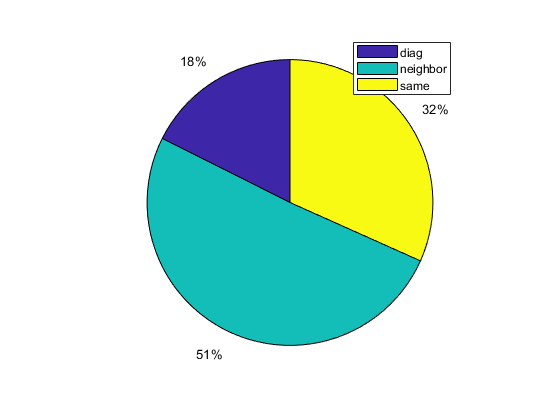

 figure, pie([p_time_spent_diag,p_time_spent_neighbor,p_time_spent_together]);legend({'diag','neighbor','same'})

## simulate random points

 yrange = [77,348]; % row
 xrange = [88,368]; % colum
 sm = [randi(xrange,10000,1),randi(yrange,10000,1),randi(xrange,10000,1),randi(yrange,10000,1)];

smqcode = [sm(:,1)<=qcenter(1), sm(:,2) > qcenter(2), sm(:,3)<=qcenter(1),sm(:,4)>qcenter(2)];
smqseries = [smqcode(:,1)+smqcode(:,2)*2,smqcode(:,3)+smqcode(:,4)*2];
smqseries(smqseries==1) = 4; smqseries(smqseries == 0) = 1;
 

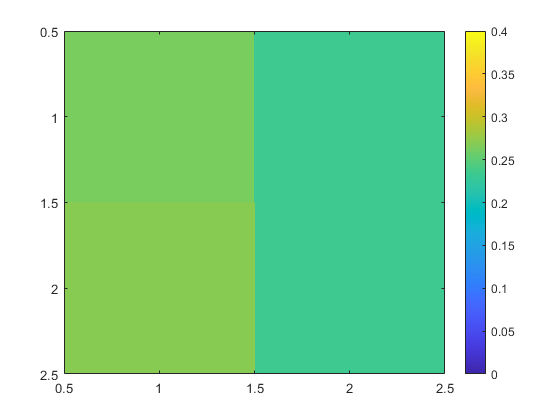

sm_quadrant_perc = zeros(2,2);
sm_quadrant_perc(1,2) = sum(smqseries(:)==1);
sm_quadrant_perc(2,2) = sum(smqseries(:)==2);
sm_quadrant_perc(2,1) = sum(smqseries(:)==3);
sm_quadrant_perc(1,1) = sum(smqseries(:)==4);
sm_quadrant_perc = sm_quadrant_perc/(2*size(smqseries,1));
figure, imagesc(sm_quadrant_perc,[0,0.4]),colorbar;

## time spent together in one quadrant/entire timespan

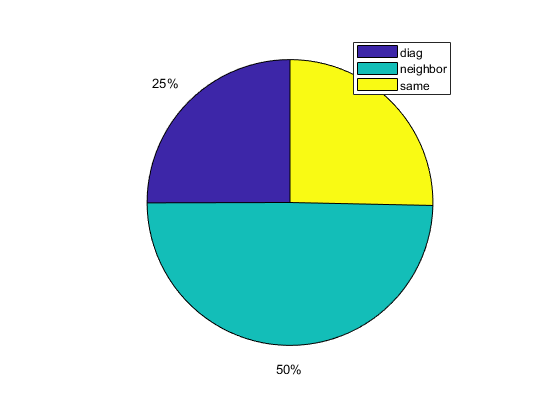

 smq_diff = diff(smqseries,[],2);
 smp_time_spent_together = sum(smq_diff == 0)/length(smq_diff);
 smp_time_spent_neighbor = sum(or(abs(smq_diff)==1,abs(smq_diff)==3))/length(smq_diff);
 smp_time_spent_diag = sum(abs(smq_diff)==2)/length(smq_diff);
 figure, pie([smp_time_spent_diag,smp_time_spent_neighbor,smp_time_spent_together]);legend({'diag','neighbor','same'});

% circshift control
t_dist = [];
for i = 1:2000
    qseries_new = [qseries(:,1), circshift(qseries(:,2), randi(round(1/4*size(qseries,1)),1))];
    q_diff = diff(qseries_new,[],2);
    p_time_spent_together = sum(q_diff == 0)/length(q_diff);
    p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff);
    p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff);
    t_dist = [t_dist;p_time_spent_together, p_time_spent_neighbor, p_time_spent_diag];
end
mt_dist = mean(t_dist,1)

mt_dist =     0.2683    0.5083    0.2235


% save tracking data
save('2994_3119.mat','track_center','qcenter','qseries','new_track','mt_dist');

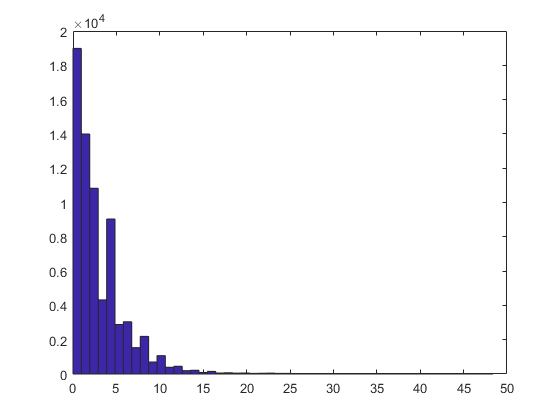

fr = 30;
track_diff = diff(track_center,[],1);
track_dist = track_diff.^2;
track_speed = sqrt([track_dist(:,1)+track_dist(:,2), track_dist(:,3)+track_dist(:,4)]);
figure,hist(track_speed(track_speed(:,1)<=50,1),50); 

% Gen a artificial track with speed and position
x_r = [77,370];
y_r = [29,319];
speed_range = track_speed(track_speed(:,1)<=50,1);
start_position = track_center(1,1:2);
[traj,walldist] = TrackGen([x_r, y_r], start_position, 30000,speed_range);


wall_dists =

     []



% visualize trajectory
traj_plot = plot(a, traj(1,1),traj(1,2),'Marker','diamond');
for i = 1:size(traj,1)
    set(traj_plot, 'XData', traj(i,1), 'YData', traj(i,2));
    drawnow;
    pause(0.03);
end